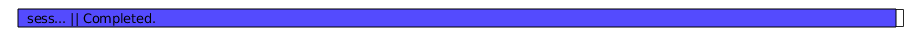

conn = sqlite('decoding_all_sess_HD_gamma.db');
sm = SessManager;
ms = sm.meta.Mouse(sm.meta.Usable);
ss = sm.meta.Session(sm.meta.Usable);
[res, res_shuf] = deal(cell(1,numel(ms)));
progressbar('sess...');
for i = 1:numel(ms)
    res{i} = conn.fetch(DecodeTensor.build_command_sess({['Mouse' ms{i}], ss{i}},...
        'unshuffled', 'MSE', 'max', 'max'));
    res_shuf{i} = conn.fetch(DecodeTensor.build_command_sess({['Mouse' ms{i}], ss{i}},...
        'shuffled', 'MSE', 'max', 'max'));
    progressbar(i/numel(ms));
end

for i = 1:numel(ms)
    mean_rms(i) = mean(sqrt(cell2mat(res{i}(:,3))));
    mean_rms_shuf(i) = mean(sqrt(cell2mat(res_shuf{i}(:,3))));
end

grand_mean_rms = mean(mean_rms)

grand_mean_rms = 11.1479

std_mean_rms = std(mean_rms)

std_mean_rms = 7.8757


grand_mean_rms_shuf = mean(mean_rms_shuf)

grand_mean_rms_shuf = 6.6070

std_mean_rms_shuf = std(mean_rms_shuf)

std_mean_rms_shuf = 6.9479

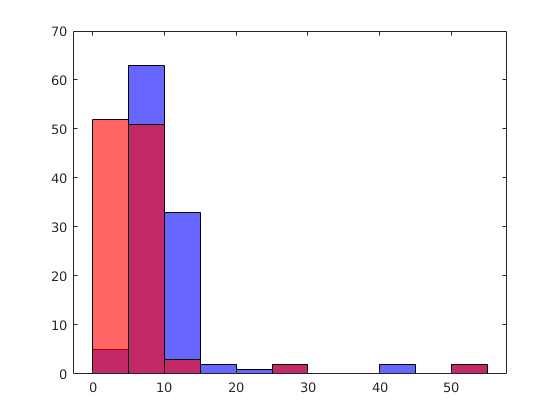

figure;
histogram(mean_rms, 'FaceColor', 'b');
hold on;
histogram(mean_rms_shuf, 'FaceColor', 'r');

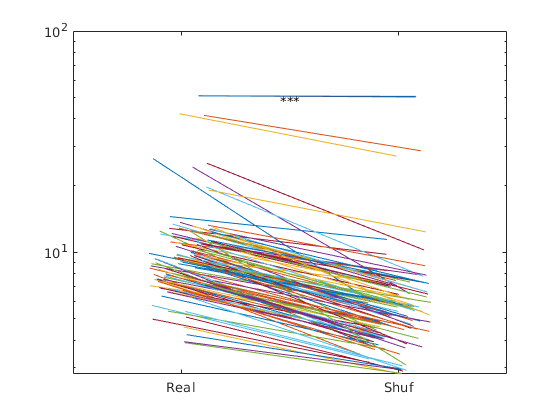

figure;
ballnstick('Real', 'Shuf', mean_rms, mean_rms_shuf);
set(gca, 'YScale', 'log');